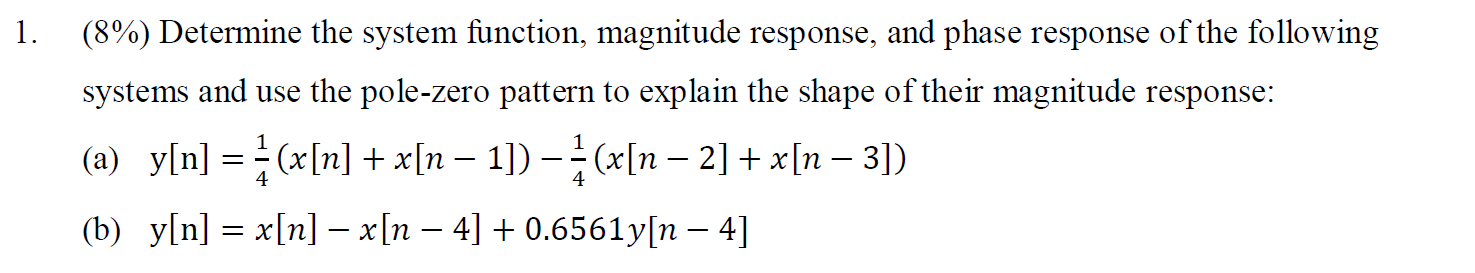

### (a)

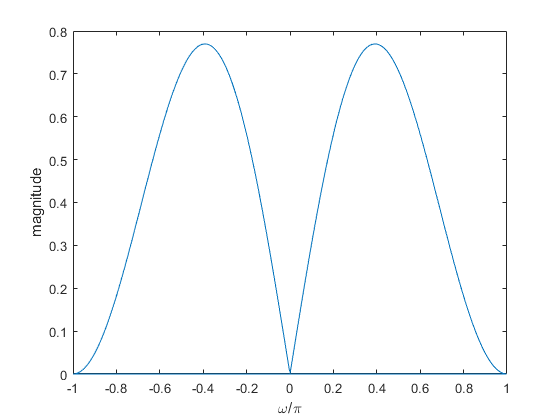

b = 1/4*[1 1 -1 -1];
a = [1 0 0 0];
[h, w] = freqz(b, a, 'whole', 1024);
w(w>=pi) = w(w>=pi)-2*pi;
w = w/pi;
plot(w, abs(h));
xlabel('\omega/\pi');
ylabel('magnitude');

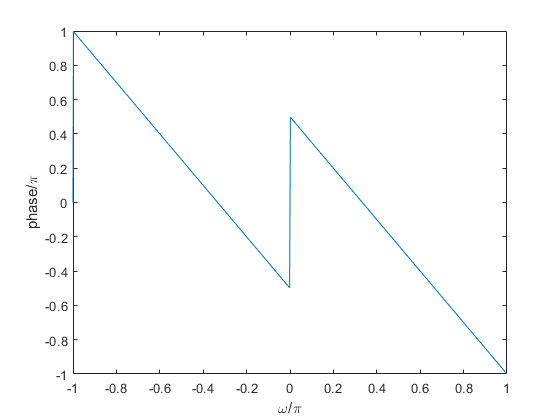

w = fftshift(w);
h = fftshift(h);
plot(w, angle(h)/pi);
xlabel('\omega/\pi');
ylabel('phase/\pi');

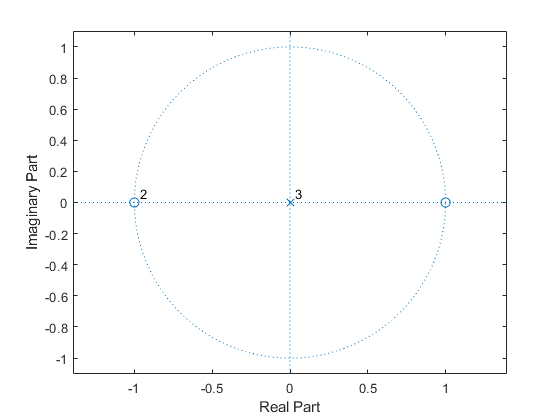

zplane(b, a);

### (b)

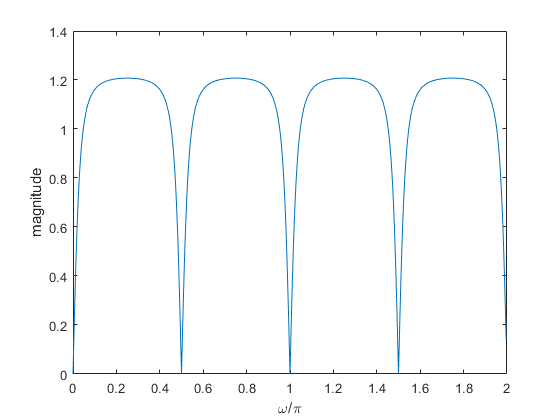

b = [1 0 0 0 -1];
a = [1 0 0 0 -0.6561];
[h, w] = freqz(b, a, 'whole');
w = w/pi;
plot(w, abs(h));
xlabel('\omega/\pi');
ylabel('magnitude');

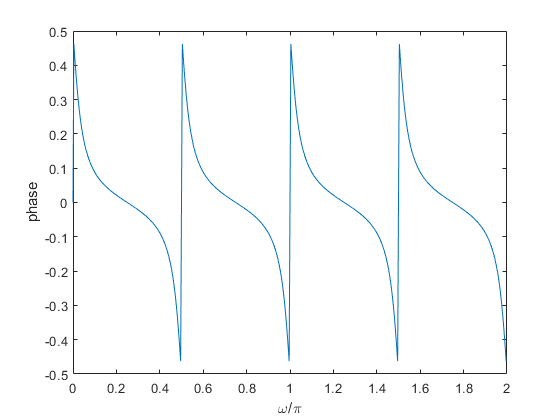

plot(w, angle(h)/pi);
xlabel('\omega/\pi');
ylabel('phase');

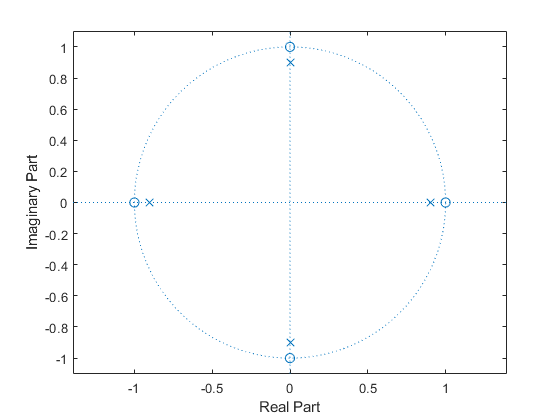

zplane(b, a);

zplane(b, a);

### 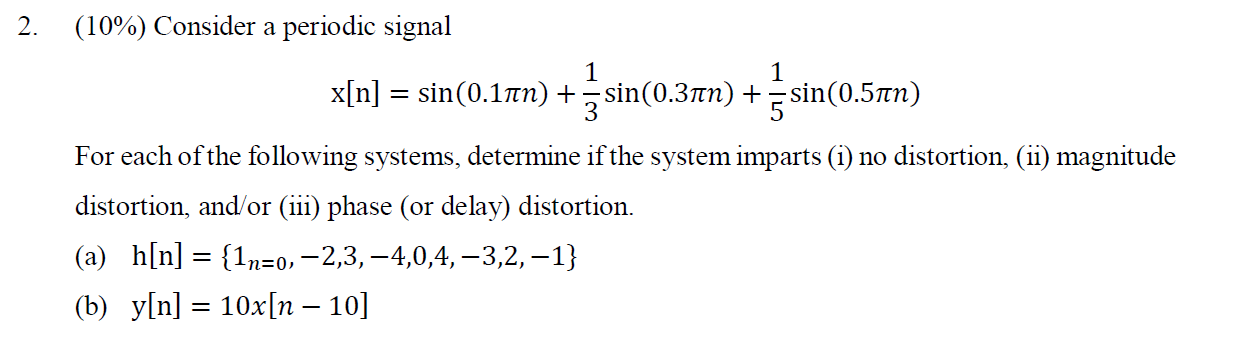 

(a)

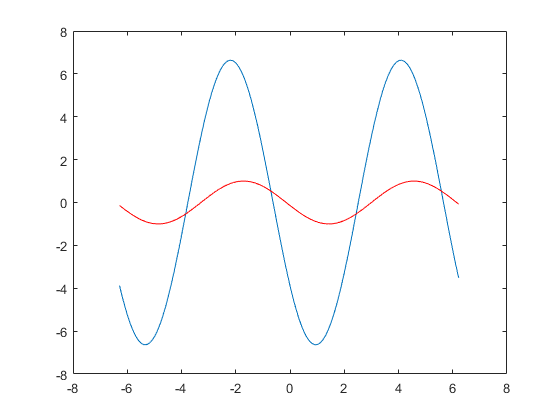

%test
x = -2*pi:0.1:2*pi;
y1 = 2*sin(x-2);
y2 = 5*sin(x-9);
plot(x, y1+y2);
hold on
plot(x, sin(x-3), 'r');
hold off

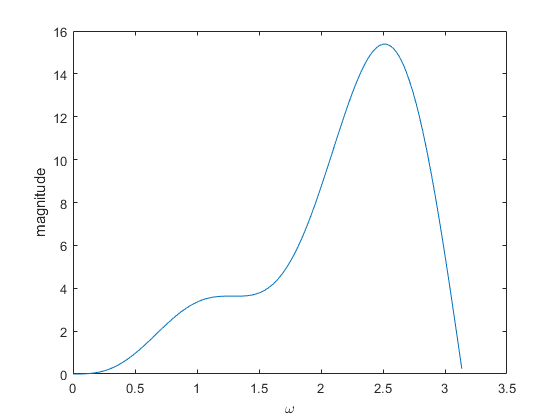

b = [1 -2 3 -4 0 4 -3 2 -1];
a = [1 0 0 0 0 0 0 0 0];
[h, w] = freqz(b, a);
plot(w, abs(h));
xlabel('\omega');
ylabel('magnitude');

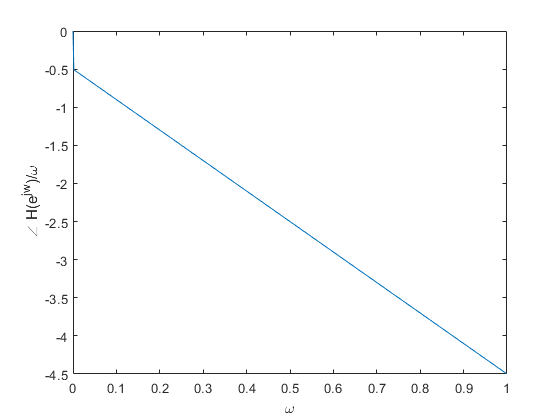

phase_h = unwrap(angle(h));
plot(w/pi, phase_h/pi);
xlabel('\omega');
ylabel('\angle H(e^{jw})/\omega');

% zplane(b, a);

(b) 

b = [0 0 0 0 0 0 0 0 0 0 10]; % by h[n]
a = [1 0 0 0 0 0 0 0 0 0 0];
%fre = [0.1*pi 0.3*pi 0.5*pi];
[h, w]=freqz(b,a); % find the frequency response of f = 0.1pi 0.3pi 0.5pi
mag_resb = abs(h)

mag_resb =    10.0000
   10.0000
   10.0000
   10.0000
   10.0000
   10.0000
   10.0000
   10.0000
   10.0000
   10.0000


phase_resb = angle(h) % use phase_delay to vertify

phase_resb =          0
   -0.0614
   -0.1227
   -0.1841
   -0.2454
   -0.3068
   -0.3682
   -0.4295
   -0.4909
   -0.5522


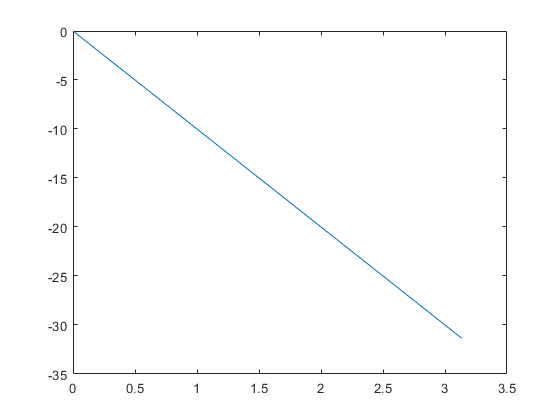

plot(w, unwrap(phase_resb));

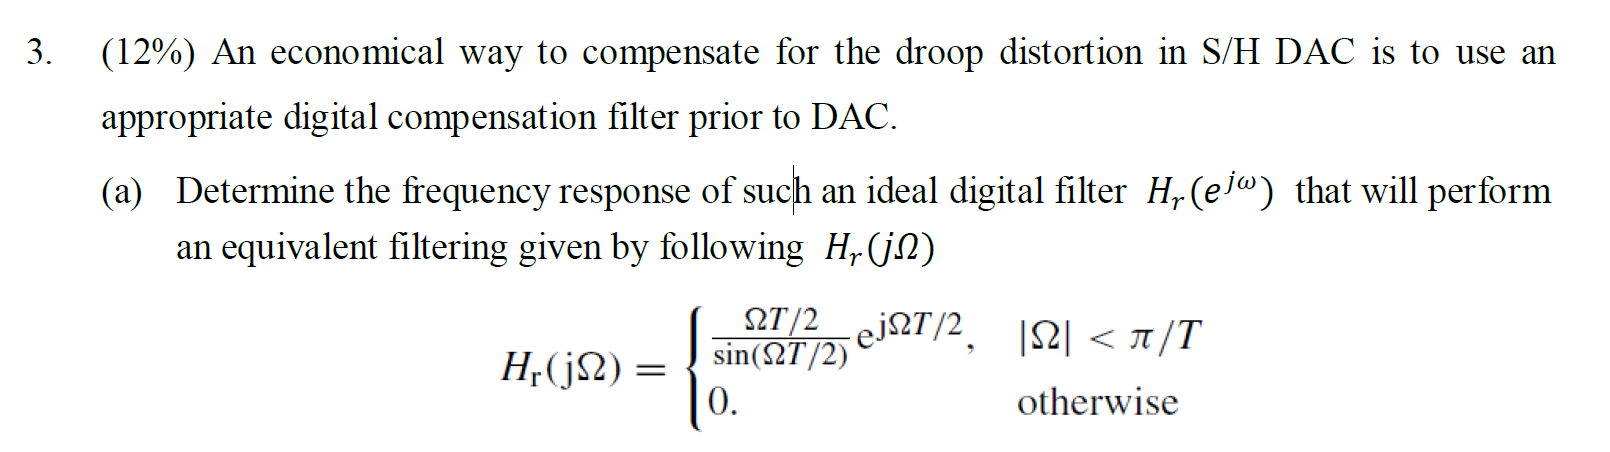

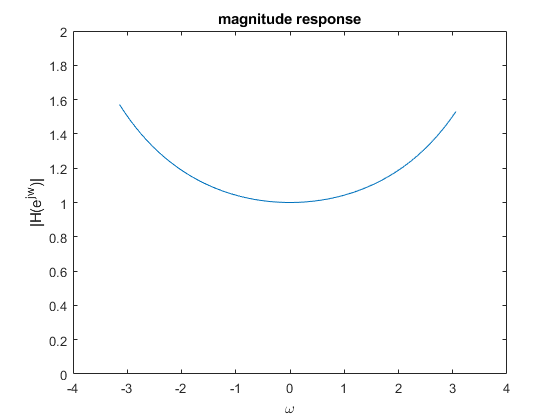

w = -pi:0.1:pi;
H = (w/2)./sin(w/2).*exp(1j*w/2);
plot(w, abs(H));
ylim([0 2]);
title('magnitude response');
xlabel('\omega');
ylabel('|H(e^{jw})|');

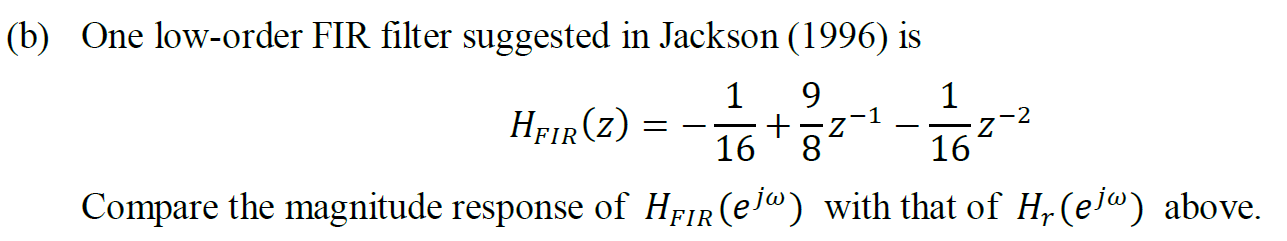

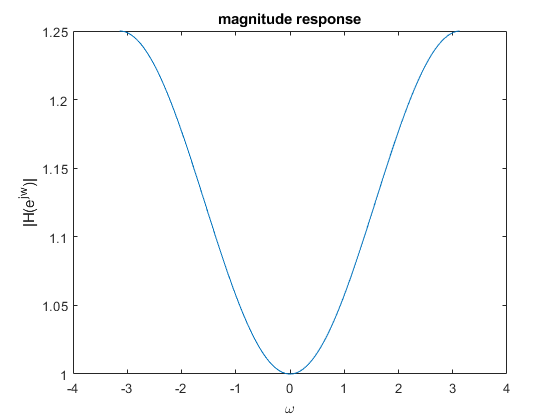

b = [-1/16, 9/8, -1/16];
a = [1 0 0];
[H, w] = freqz(b, a, 'whole');
w(w >= pi) = w(w >= pi)-2*pi;
w = fftshift(w);
H = fftshift(H);
plot(w, abs(H));
title('magnitude response');
xlabel('\omega');
ylabel('|H(e^{jw})|');

%ylim([0.8, 1.4]);

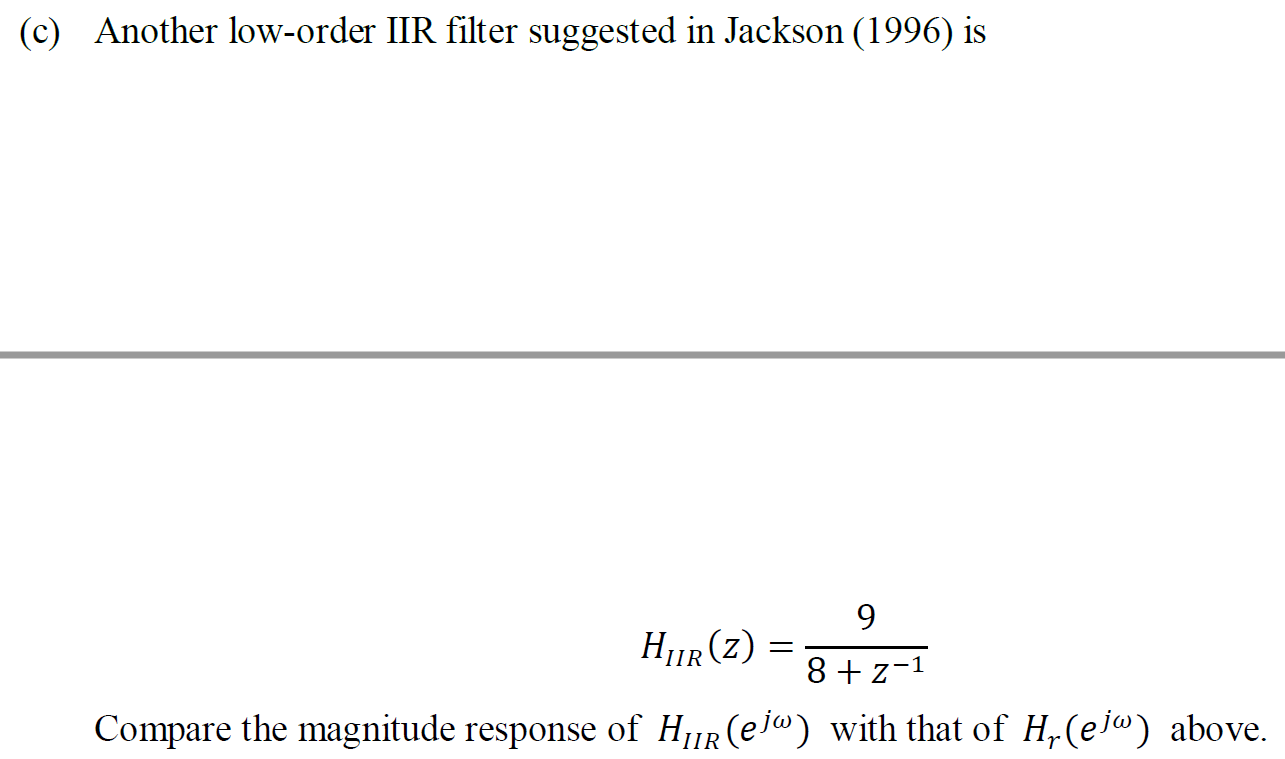

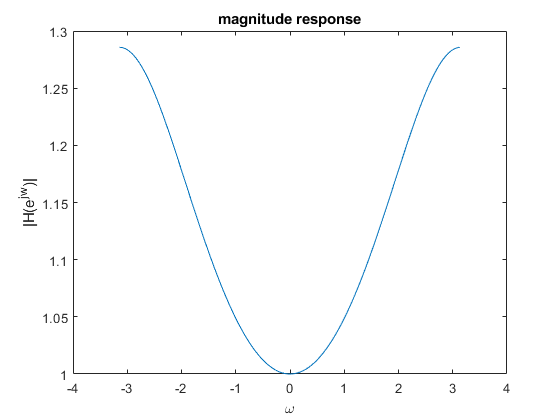

b = [9 0];
a = [8 1];
[H, w] = freqz(b, a, 'whole');
w(w >= pi) = w(w >= pi)-2*pi;
w = fftshift(w);
H = fftshift(H);
plot(w, abs(H));
title('magnitude response');
xlabel('\omega');
ylabel('|H(e^{jw})|');

%ylim([0.8, 1.4]);

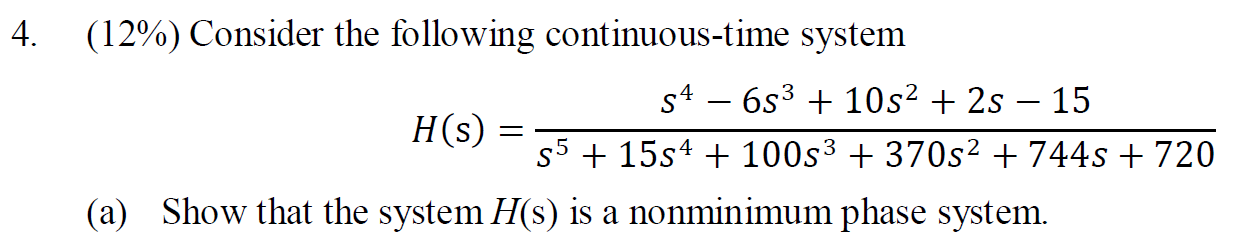

H = tf([1 -6 10 2 -15],[1 15 100 370 744 720]);
[p,z] = pzmap(H)

p =   -5.0000 + 0.0000i
  -3.0000 + 3.0000i
  -3.0000 - 3.0000i
  -2.0000 + 2.0000i
  -2.0000 - 2.0000i


z =    3.0000 + 0.0000i
   2.0000 + 1.0000i
   2.0000 - 1.0000i
  -1.0000 + 0.0000i


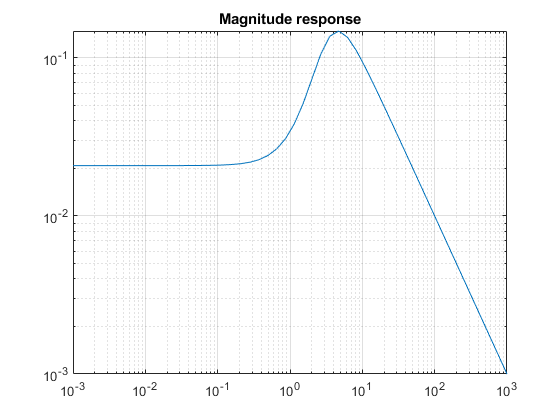

b = [1 -6 10 2 -15];
a = [1 15 100 370 744 720];
w = logspace(-3,3);

h = freqs(b,a, w);
loglog(w, abs(h));
title('Magnitude response');
grid on

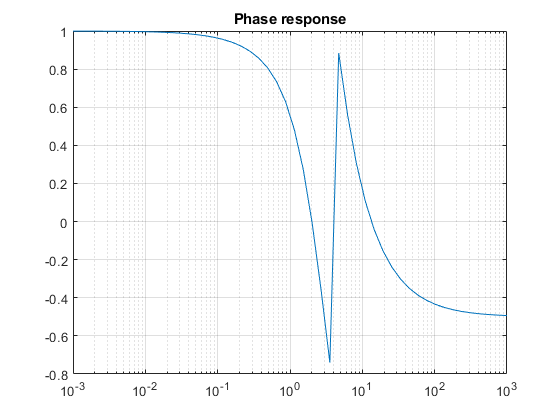

semilogx(w, angle(h)/pi);
title('Phase response');
grid on

% Hmin(s)
z = [-1 -3 -2-1j -2+1j];   % Zeros
p = [-5 -3+3j -3-3j -2+2j -2-2j];     % Poles
k = 1;                     % Gain (constant at numerator)
H = zpk(z,p,k)


H =
 
       (s+1) (s+3) (s^2 + 4s + 5)
  ------------------------------------
  (s+5) (s^2 + 4s + 8) (s^2 + 6s + 18)
 
Continuous-time zero/pole/gain model.



H = tf(H)


H =
 
         s^4 + 8 s^3 + 24 s^2 + 32 s + 15
  ----------------------------------------------
  s^5 + 15 s^4 + 100 s^3 + 370 s^2 + 744 s + 720
 
Continuous-time transfer function.



[num,den] = tfdata(H,'v');    %'v' return numerial arrya, without it, return cell array
b = num;
a = den;
h = freqs(b,a, w);
loglog(w, abs(h));
title('Magnitude response');
grid on

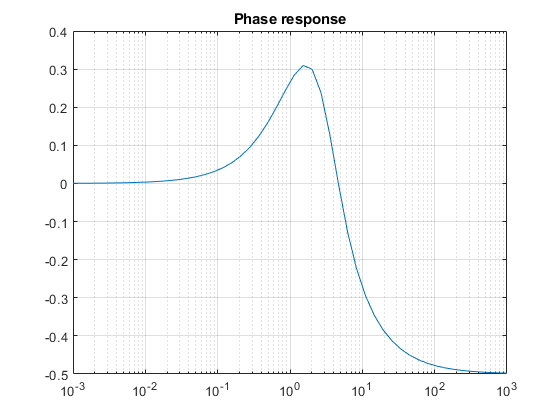

semilogx(w, angle(h)/pi);
title('Phase response');
grid on

z = [3 2+1j 2-1j];   % Zeros
p = [-3 -2-1j -2+1j];     % Poles
k = 1;                     % Gain (constant at numerator)
H = zpk(z,p,k)


H =
 
  (s-3) (s^2 - 4s + 5)
  --------------------
  (s+3) (s^2 + 4s + 5)
 
Continuous-time zero/pole/gain model.



H = tf(H)


H =
 
  s^3 - 7 s^2 + 17 s - 15
  -----------------------
  s^3 + 7 s^2 + 17 s + 15
 
Continuous-time transfer function.



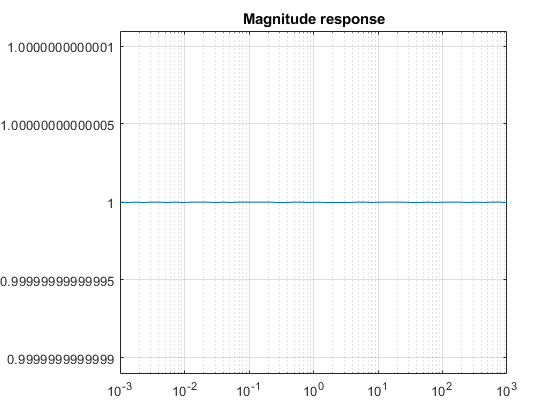

[num,den] = tfdata(H,'v');    %'v' return numerial arrya, without it, return cell array
b = num;
a = den;
h = freqs(b,a, w);
semilogx(w, abs(h));
title('Magnitude response');
grid on

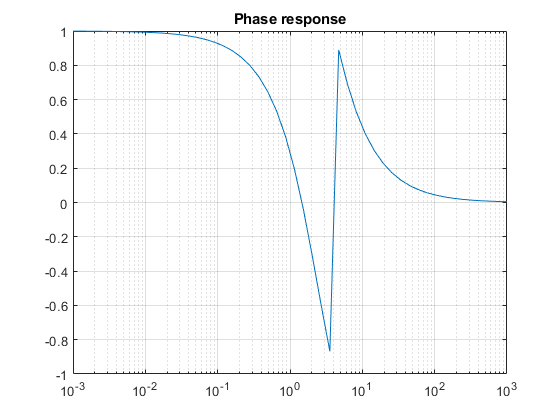

semilogx(w, angle(h)/pi);
title('Phase response');
grid on

5. 

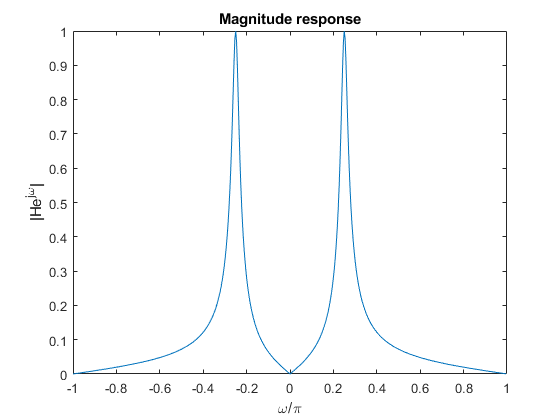

z = [1 -1]';
p = [0.95*exp(1j*pi/4), 0.95*exp(-1j*pi/4)];
k = 0.048766;
[b, a] = zp2tf(z, p, k);
[h, w] =freqz(b, a, 'whole');
w(w >= pi) = w(w >= pi)-2*pi;
w = fftshift(w);
h = fftshift(h);
plot(w/pi, abs(h));
title('Magnitude response');
xlabel('\omega/\pi');
ylabel('|He^{j\omega}|');

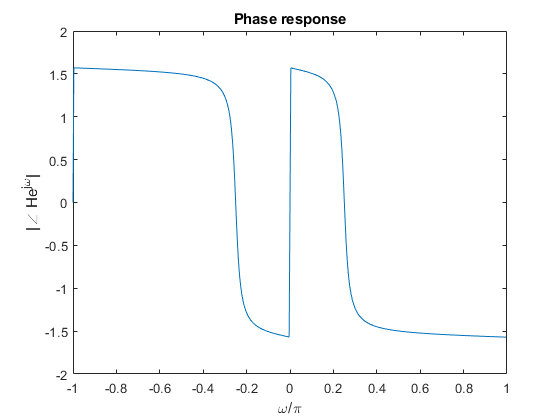

Ang_h = unwrap(angle(h));
plot(w/pi, Ang_h);
title('Phase response');
xlabel('\omega/\pi');
ylabel('|\angle He^{j\omega}|')

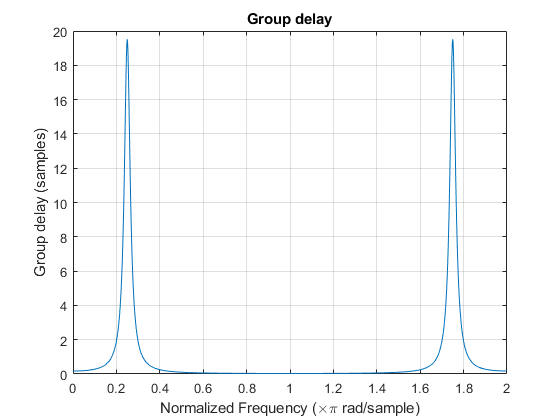

grpdelay(b, a, 1024, 'whole');
title('Group delay');

6.

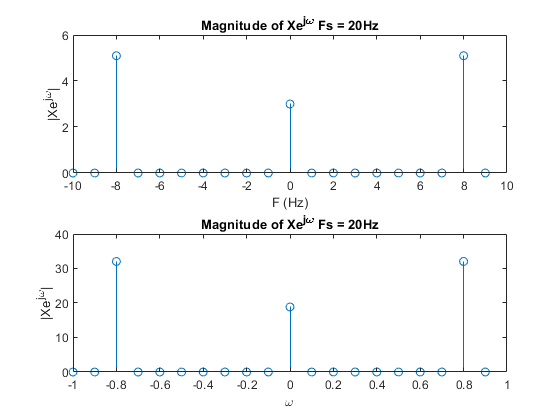

Fs = 20;
t = 0:1/Fs:1-(1/Fs);
%N = length(t)/20;     %as period is 1/50 and 1s is 20

xc = 3 + 2*sin(16*pi*t) + 10*cos(24*pi*t);
X = dtfs(xc);
freq = -10:(Fs/length(X)):10-(Fs/length(X));
figure;
subplot(2, 1, 1);
stem(freq, abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 20Hz');
xlabel('F (Hz)');
ylabel('|Xe^{j\omega}|');
subplot(2, 1, 2);
w = 2*pi*freq/Fs;
stem(w/pi, 2*pi*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 20Hz');
xlabel('\omega');
ylabel('|Xe^{j\omega}|');

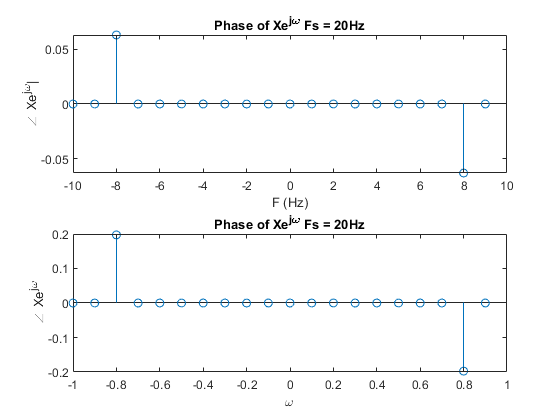

figure;
subplot(2, 1, 1);
stem(freq, angle(round(fftshift(X)))/pi);
title('Phase of Xe^{j\omega} Fs = 20Hz');
xlabel('F (Hz)');
ylabel('\angle Xe^{j\omega}|');
subplot(2, 1, 2);
w = 2*pi*freq/Fs;
stem(w/pi, angle(round(fftshift(X))));
title('Phase of Xe^{j\omega} Fs = 20Hz');
xlabel('\omega');
ylabel('\angle Xe^{j\omega}');